# Circles vs ellipses

## Make data

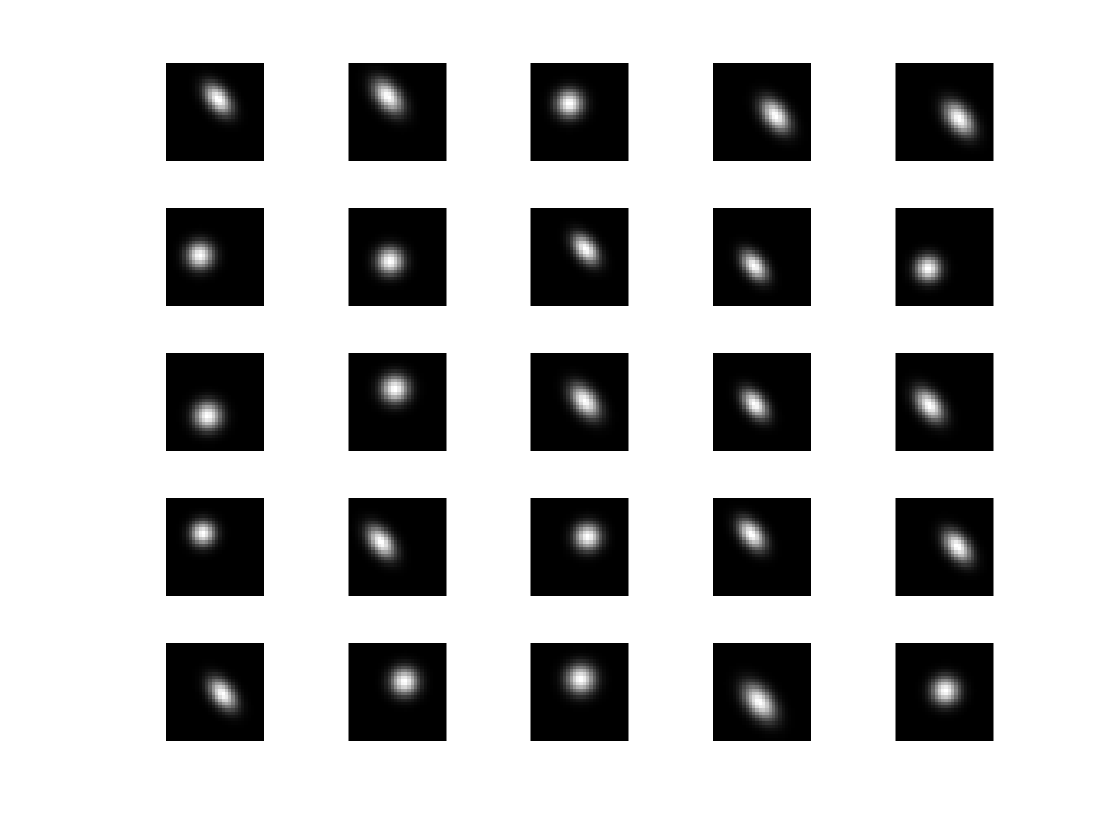

clear all; 
m = 30; % image size 30-by-30
n1 = 100;
n2 = 120;
n = n1+n2;
D1 = 1:n1;
D2 = (n1+1):n;
col = ['r','b'];
f = @(x,y,x0,y0,a11,a12,a22)exp(-0.5*(a11*(x-x0).^2+...
    2*a12*(x-x0).*(y-y0)+a22*(y-y0).^2));
[xx,yy] = meshgrid(1:30,1:30);
A1 = eye(2);
A2 = [1.25,-0.5;-0.5,1];
x0 = rand(n,1)*10+10; % uniform[10,20]
y0 = rand(n,1)*10+10; % uniform[10,20]
fac = 0.125+0.0125*randn(n,1);
X1 = zeros(n1,m*m);
for j = 1 : n1
    A = A1*max(0.01,min(fac(j),2));
    x = f(xx,yy,x0(j),y0(j),A(1,1),A(1,2),A(2,2));
    X1(j,:) = x(:)';
end
X2 = zeros(n2,m*m);
for j = 1 : n2
    A = A2*fac(n1+j);
    x = f(xx,yy,x0(n1+j),y0(n1+j),A(1,1),A(1,2),A(2,2));
    X2(j,:) = x(:)';
end
X = [X1;X2];
close all;
figure;
hold on;
p=randperm(n,25);
for k = 1 : 25
    subplot(5,5,k);
    imagesc(reshape(X(p(k),:)',[m,m]));
    colormap gray
    daspect([1,1,1])
    axis off
end

## Fisher linear discriminant

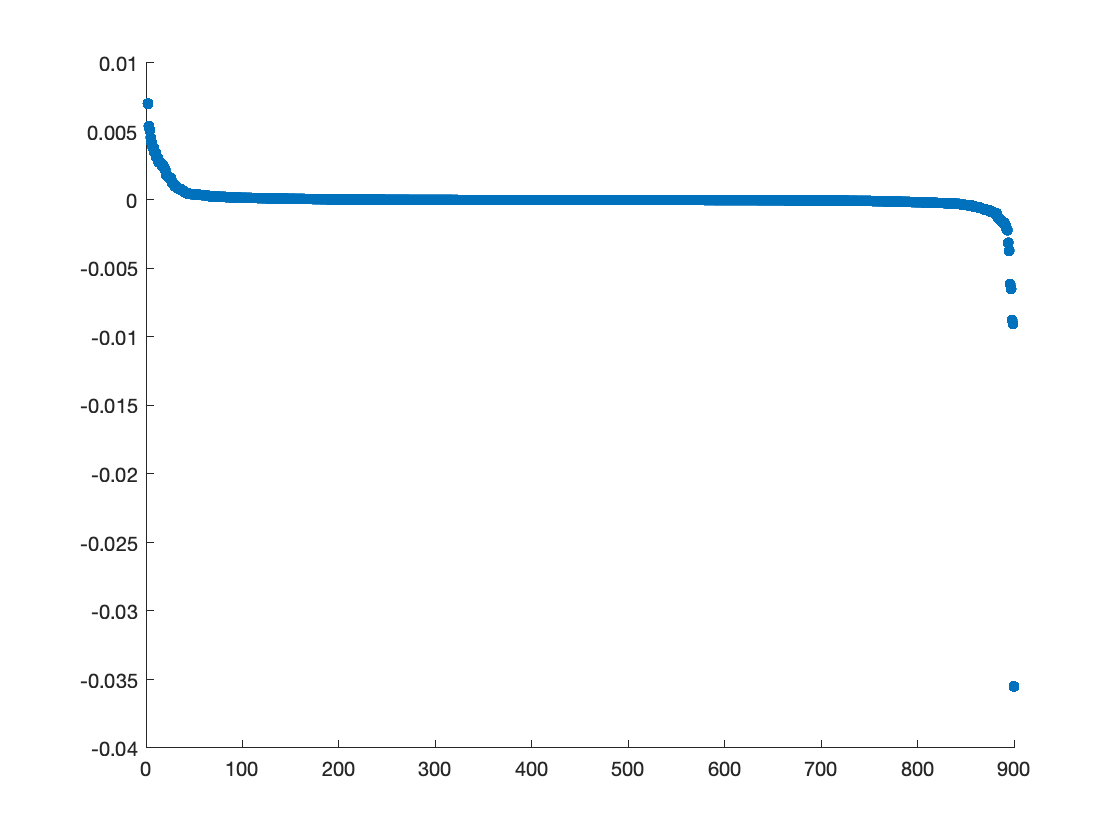

m1 = mean(X(D1,:),1);
m2 = mean(X(D2,:),1);
X1 = X(D1,:);
X2 = X(D2,:);
Xc1 = X1-ones(n1,1)*m1;
S1 = Xc1'*Xc1;
Xc2 = X2-ones(n2,1)*m2;
S2 = Xc2'*Xc2;
Sw = S1+S2;
% note: d = m*m > n, hence we solve
% the generalized eigenvalue problem
Sb = (m1-m2)'*(m1-m2);
[W,lam0] = eig(Sb,Sw);
lam = diag(lam0);
[lam,isort] = sort(lam,'descend');
figure;
hold on;
plot(lam,'.','Markersize',15);

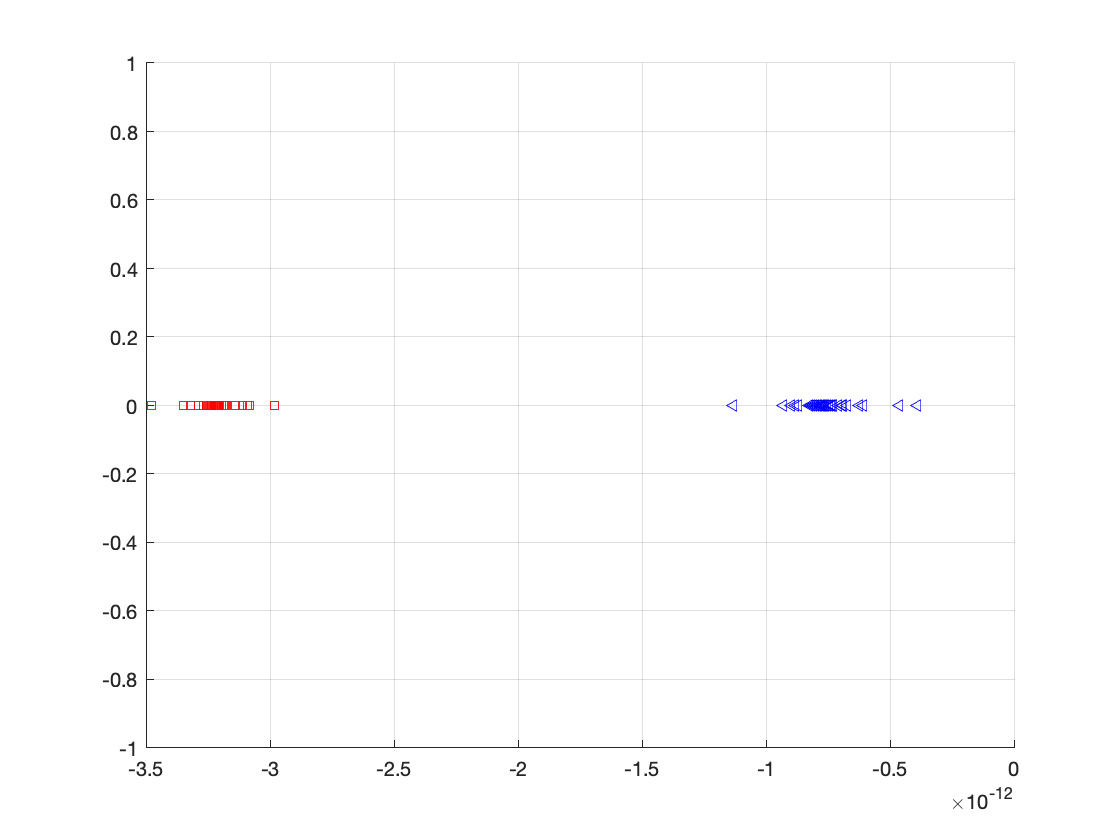

W = W(:,isort);
w = W(:,1); % pick eigenvector corresponding to the larges eval
% graphics
% map to 1D
figure;
hold on; grid;
y = X*w;
plot(y(D1),zeros(n1,1),'s','color','none',...
    'Markeredgecolor',col(1),'Markersize',5);
plot(y(D2,1),zeros(n2,1),'<','color','none',...
    'Markeredgecolor',col(2),'Markersize',5);